# ThermoeconomicModel demo

Analyze an ORC system with IHE (*rorc_model*) using the base function ThermoeconomicModel

#### **Create the Thermoeconomic Model**

the data file and create the model with some parameters. 

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
model=ThermoeconomicModel(filename,...
    'CostTables','ALL',...
    'DiagnosisMethod','WASTE_INTERNAL',...
    'Debug',false);

#### **Show the results for Reference State**

Print the result tables and show ICT and waste allocation graphs

model.showResults;


Flows Definition Table - REF

  Id Key   From    To      Type      
——————————————————————————————————————
   1 B1    BLR_P1  TRB_F1  INTERNAL  
   2 B2    TRB_F1  IHE_F1  INTERNAL  
   3 B3    IHE_F1  CND_F1  INTERNAL  
   4 B4    CND_F1  PMP_P1  INTERNAL  
   5 B5    PMP_P1  IHE_P1  INTERNAL  
   6 B6    IHE_P1  BLR_P1  INTERNAL  
   7 QBLR  ENV_R1  BLR_F1  RESOURCE  
   8 WP    TRB_P1  PMP_F1  INTERNAL  
   9 WN    TRB_P1  ENV_O1  OUTPUT    
  10 QCND  CND_P1  ENV_W1  WASTE     


Productive Groups Definition Table - REF

  Id Key     Definition  Type      
————————————————————————————————————
   1 BLR_F1  QBLR        FUEL      
   2 BLR_P1  B1-B6       PRODUCT   
   3 TRB_F1  B1-B2       FUEL      
   4 TRB_P1  WN+WP       PRODUCT   
   5 IHE_F1  B2-B3       FUEL      
   6 IHE_P1  B6-B5       PRODUCT   
   7 PMP_F1  WP          FUEL      
   8 PMP_P1  B5-B4       PRODUCT   
   9 CND_F1  B3-B4       FUEL      
  10 CND_P1  QCND        PRODUCT   
  11 ENV_R1  QBLR        RESOURCE  

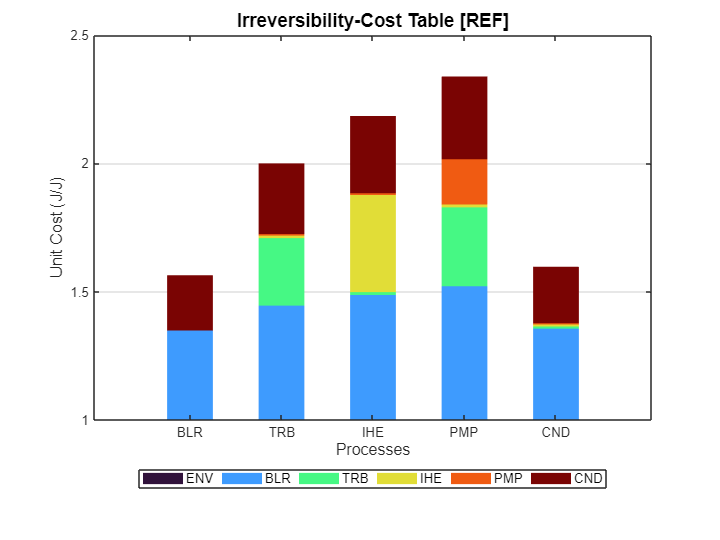

showGraph(model,cType.Tables.PROCESS_ICT);

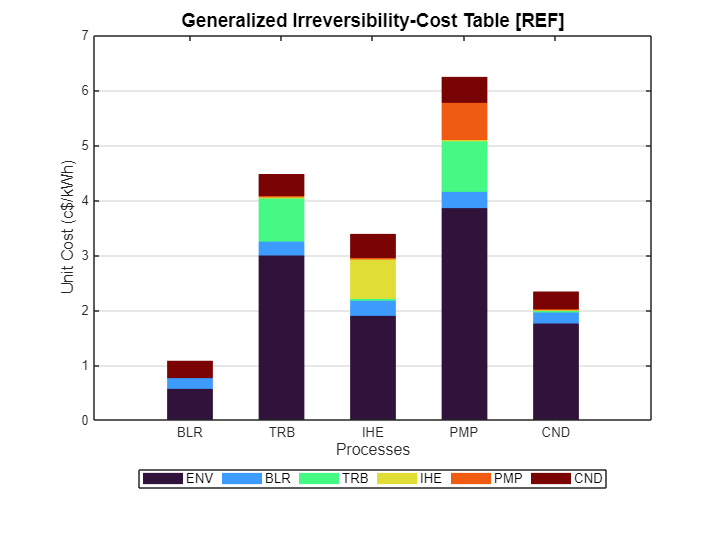

ShowGraph(model,'Graph',cType.Tables.PROCESS_GENERAL_ICT);

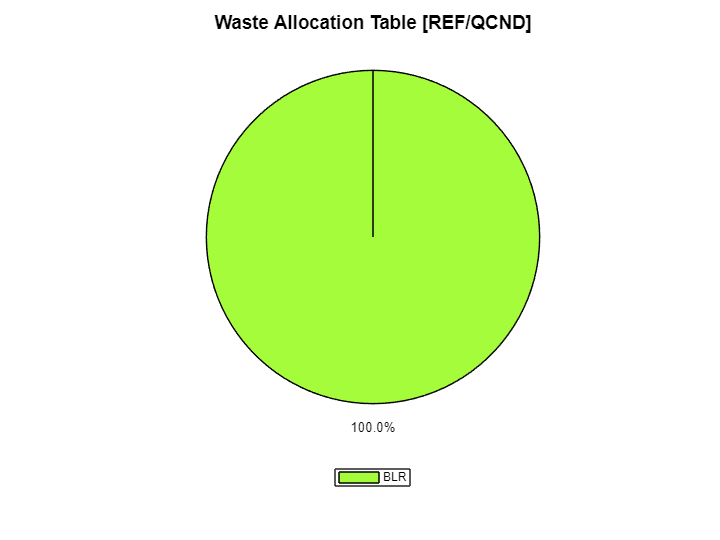

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION);

#### Save the Results

Save the results into a file, using diferent file types

save=true;
type="xlsx";
if save
    filename=strcat("model_result.",type);
    SaveResults(model,filename);
end

INFO: cMessageLogger. File model_result.xlsx has been saved


#### **Summary Results**

Select the summary options available

SummaryOptions=convertCharsToStrings(model.summaryOptions);
option=convertStringsToChars(SummaryOptions(3));
model.setSummary(option);

Show unit cost summary tables and graph

if model.isSummaryEnable 
    res=model.summaryResults;
    showResults(res,cType.Tables.SUMMARY_FLOW_UNIT_COST);
    showResults(res,cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);
    showGraph(res,cType.Tables.SUMMARY_FLOW_UNIT_COST);
    showGraph(res,cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);
end

ERROR: cMessageLogger. Table dfuc is NOT available


ERROR: cMessageLogger. Table gfuc is NOT available


ERROR: cResultInfo. Invalid graph table: dfuc


ERROR: cResultInfo. Invalid graph table: gfuc


#### Diagnosis Analysis

Analyze a malfunction in the plant

States=convertCharsToStrings(model.StateNames);
state=convertStringsToChars(States(3));
model.setState(state);
model.summaryDiagnosis;
showResults(model,cType.Tables.DIAGNOSIS);
showGraph(model,cType.Tables.MALFUNCTION_COST,false);

#### **Recycling Analysis**

Select the model without IHE and analyse the capability of recycling

model.setRecycling(true);
setDiagnosisMethod(model,'NONE');
model.setState('noIHE');
showResults(model,cType.Tables.WASTE_RECYCLING_GENERAL);
showGraph(model,cType.Tables.WASTE_RECYCLING_DIRECT);
showGraph(model,cType.Tables.WASTE_RECYCLING_GENERAL);

#### Additional Help

help ThermoeconomicModel